### COMPRESSED SENSING AND ITS APPLICATIONS

### DONE BY :

### DEEPTHI SUDHARSAN (CB.EN.U4AIE19022)

### MEGHNA B MENON (CB.EN.U4AIE19043)

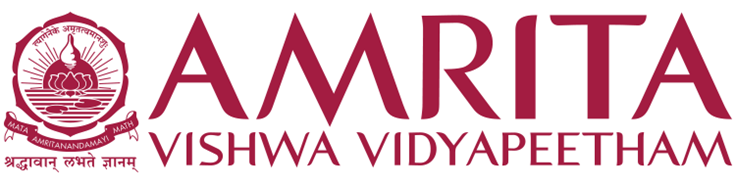

**B.TECH CSE-AI, CEN DEPARTMENT, AMRITA SCHOOL OF ENGINEERING**

## COMPRESSED SENSING 

Compressed sensing is a signal processing technique which helps in efficiently recovering, processing and reconstructing a signal (by sampling it at a rate much below the Nyquist sampling rate), by finding **sparse **solutions to underdetermined linear systems (System of linear equations, with more equations than unknowns).

Nyquist Rate  : For effective reproduction, the sampling rate should be twice the highest frequency in the signal, this sampling rate is called as Nyquist rate. Nyquist sampling rate fs = 2W where W is the highest frequency.

### Why Sparsity?

We let the constraint of sparsity come into picture so as to allow only solutions which have small number of non-zero coefficients to the underdetermined linear system. It is not necessary that all underdetermined linear system solutions need to be sparse, but if the system has a unique sparse solution, recovery of the solution is easier. If the solution is sparse, it is compressible and recovery is possible in minimum number of steps. 

### ** Role of L1 – Regularization**

Let us look at a small example for our better understanding. Suppose we have all the vowels of the Hindi language and we want to train a classifier into classifying the different vowels based on any similarity or constraint that too in a smaller number of iterations or steps. What we do is as follows. We take the training data set and numerically label all of them like below:     

                                                                                                                                                                       

Now, our goal is to break-down the training data set into a set of smaller datasets derived from the complete training data and create/represent them as sparse vectors. For example, taking the similarity of the curves or lines into consideration, we can create this “measurement matrix”. 

          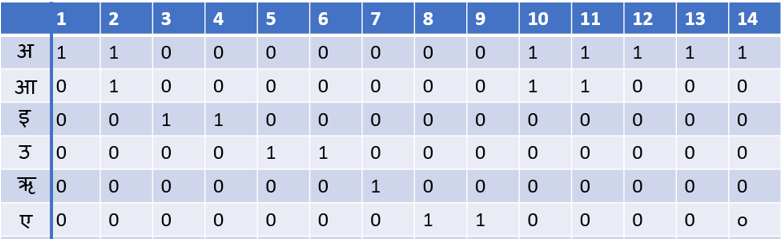

When we are solving for a large vector x with less training data ( Solving Ax=b where A matrix consists of the training data, x is the solution vector we want and b is the label vector), there can be many solutions for x, even infinite! To find good solutions amongst these solutions,   we should make sure that each component selected from solution vector x contains only important and necessary features of the data. By L1 regularization, we are basically making the x vector smaller by making them sparse (sparse vectors contain less non-zero values/useful values and many useless values (zeros) that we can ignore).

### **L1 – norm Visualization**

We can visualize L1-norm this way,

                     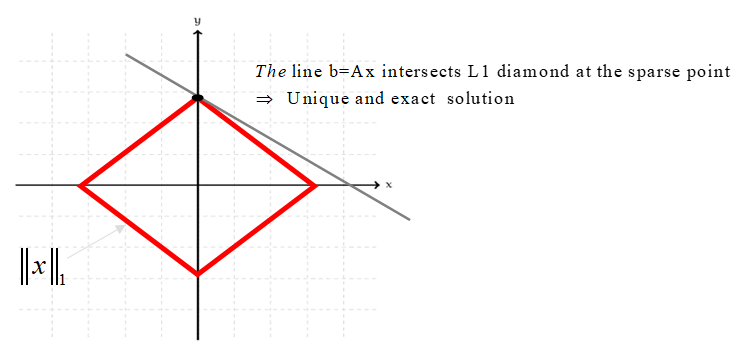

              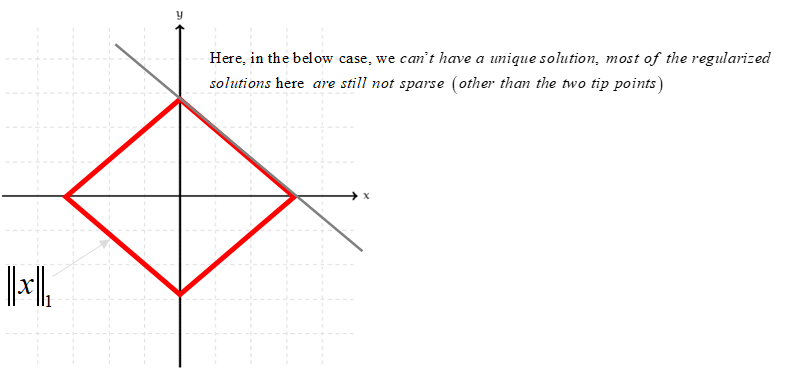

## COMPRESSED SENSING USING L1 - REGULARIZATION

###  **Problem 1:**

Consider this given problem : There are 7 gold coins, six of  2-grams and one coin of  1.8 grams.  

How will you identify the coin with 1.8 gram with minimum number of weighing?

                                         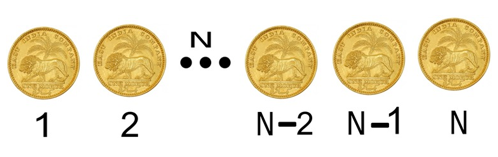

Note: Here, N=7.

Let us firstly number the gold coins given at hand from 1 till 7. 

We will make three measurements (since we are taking 4 coins in each measurement, if we take 4-1=3 measurements to know which one is the counterfeit) with different sets of coins. We represent the combination with a sparse binary tuple vector with 0 meaning that the coin with the corresponding index number label has not been selected for the measurement and 1 meaning that the coin has been chosen in that measurement. 

Let three rows of matrix A (measurement matrix) represent those vectors

                                             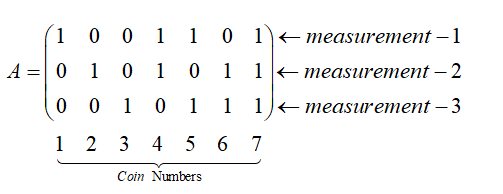

                                                    Figure : Measurement matrix

We notice a trend in the occurrence of each coin in all the measurements.

     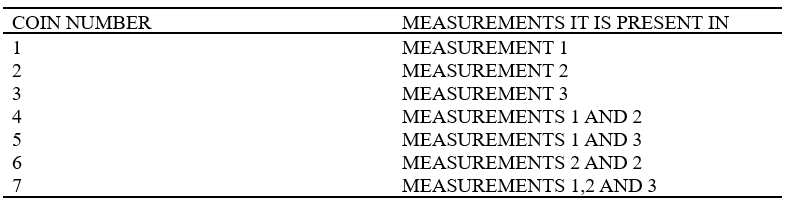

Now that we know this trend. Let us analyze the measurements that we got. Since in each measurement 4 random coins have been chosen and weighed, the total weight of the 4 coins would be 8g (4 x 2g) if they were all real gold coins. If there were any counterfeit coins, then the weight of the 4 coins would be lesser than 8g. 

Analyzing the above trend and the measurements that we have gotten after weighing the coins, we can infer the following:

Coin #1 can be a counterfeit coin if the measurement 1 alone is below 8g.

Coin #2 can be a counterfeit coin if the measurement 2 alone is below 8g.

Coin #3 can be a counterfeit coin if the measurement 3 alone is below 8g.

Coin #4 can be a counterfeit coin if the measurements 1 and 2 alone are below 8g.

Coin #5 can be a counterfeit coin if the measurement 1 and 3 alone are below 8g.

Coin #6 can be a counterfeit coin if the measurement 2 and 3  alone are below 8g.

Coin #7 can be a counterfeit coin if all the measurements are below 8g.

Now, we shall see how we can approach the solution using optimization theory.


$$\textrm{Step}\;1:\textrm{We}\;\textrm{take}\;3\;\textrm{measurements}\;m=\;\;\left\lbrack \begin{array}{c}
m_1 \\
m_2 \\
m_3 
\end{array}\right\rbrack$$



$$\textrm{Step}\;2:\textrm{We}\;\textrm{compute}\;b=\;\left\lbrack \begin{array}{c}
8\\
8\\
8
\end{array}\right\rbrack -\;\left\lbrack \begin{array}{c}
m_1 \\
m_2 \\
m_3 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{c}
{8-m}_1 \\
{8-m}_2 \\
{8-m}_3 
\end{array}\right\rbrack$$


Here, the vector from which we are subtracting the measurements that we have gotten is the expected measurements assuming that all the coins chosen in all the three measurements aren’t counterfeit. 


$$\begin{array}{l}
\textrm{Step}\;3:\textrm{Solve}\;\textrm{the}\;\textrm{Optimization}\;\textrm{Problem}\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\min \;\sum_{i=1}^{N=7} \left|x_i \right|\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{subject}\;\textrm{to}\;\textrm{Ax}=b\;
\end{array}$$


 **MATLAB CODE:**

A= [1  0  0  1  1 0 1; 0 1 0 1 0 1 1; 0 0 1 0 1 1 1];
b=[0;0.2;0.2];
cvx_begin quiet
variable x(7)
minimize( norm(x,1))
subject to
        A*x==b;
cvx_end
disp("solution vector is")

solution vector is


x

x =    -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.2000
    0.0000


Since (8 – measurement 6 = 0.2, then the counterfeit coin is coin number 6).

### **Problem 2:**

Given that there are 100 coins and out of them 10 are faulty, how do we identify the coins with say 10 measurements? 

 **MATLAB CODE:**

A=randi([0 1],40,100);
% 40x100 matrix with values either 0 or 1
xx=zeros(100,1);
k=5:10:100;
% k gives the index where faulty coin is present
% b1 gives  deviation from standard value 
b1=rand(length(k),1);
% put deviation appropriate position in xx vector
xx(k)=b1;
% Find measurement values and store in b vector
b=A*xx;
% now we try to get the solution back
cvx_begin quiet
variable x(100)
minimize(norm( x,1))
subject to
        A*x==b;
cvx_end
disp("solution vector is")

solution vector is


x

x =    -0.0000
    0.0000
    0.0000
    0.0000
    0.5520
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


## COMPRESSED SENSING USING ADMM  

## (ALTERNATING DIRECTION METHOD OF MULTIPLIERS)

Optimization is finding the best/optimum output by maximizing or minimizing a given function such that it  also satisfies certain constraints. ADMM is a powerful iterative algorithm that solves convex optimization problems (optimization problems wherein the objective function or any of the constraints are convex in nature) by breaking them into smaller pieces. The classic ADMM splits a complex problem into subproblems which is easy to solve.

 Basis pursuit is often used for finding a sparse solution to an underdetermined system of linear equations. From the role of Compressed sensing and the use of sparsity that was discussed in the previous sections, we can say that Basis Pursuit plays a central role in the theory of compressed sensing.

The Basis Pursuit minimization problem is given as follows:


$$\begin{array}{l}
\textrm{minimize}\;{\left\|x\right\|}_1 \\
\textrm{subject}\;\textrm{to}\;\textrm{Ax}=b
\end{array}$$


This can be rewritten in ADMM form as,

 
$$\begin{array}{l}
\mathrm{minimize}\;{f\left(x\right)+\left\|z\right\|}_1 \\
\mathrm{subject}\;\mathrm{to}\;x-z=0\\
\mathrm{where},f\left(x\right)\;\mathrm{is}\;\mathrm{an}\;\mathrm{indicator}\;\mathrm{function}\\
f\left(x\right)={\left\lbrace \right.}_{\infty \;,\mathrm{otherwise}}^{0\;\;,\;\mathrm{Ax}=b} 
\end{array}$$


Augmented Lagrangian Function :


$$\begin{array}{l}
L_{\rho } \left(x,z,u\right)=f\left(x\right)+{\left\|z\right\|}_1 +\frac{\rho }{2}{\left\|x-z+u\right\|}_2^2 \\
\textrm{where},\frac{\rho }{2}\;\textrm{is}\;\textrm{the}\;\textrm{penalty}\;\textrm{parameter}\\
\textrm{and}\;{\left\|x-z+u\right\|}_2^2 \;\textrm{is}\;\textrm{the}\;\textrm{norm}\;\textrm{of}\;\textrm{the}\;\textrm{vector}\;\textrm{os}\;\textrm{the}\;\textrm{equality}\;\textrm{constraints}\ldotp 
\end{array}$$


Now for the ADMM updates:


$$\begin{array}{l}
x^{k+1} =\Pi \left(z^k -u^k \right)\\
\textrm{where},\Pi \;\textrm{stands}\;\textrm{for}\;\textrm{the}\;\textrm{projection}\;\textrm{of}\;x^k =\left(z^k -u^k \right)\;\textrm{onto}\;\textrm{Ax}=b\\
\Rightarrow x^{k+1} =\left(I-A^T {\left(AA^T \right)}^{-1} A\right)\left(z^k -u^k \right)+A^T {\left(AA^T \right)}^{-1} b\;
\end{array}$$


How?

We have to find $x^{k+1}$such that it satisfies Ax=b

i.e., $x^{k+1}$ should be the closest vector in the affine space defined by Ax=b

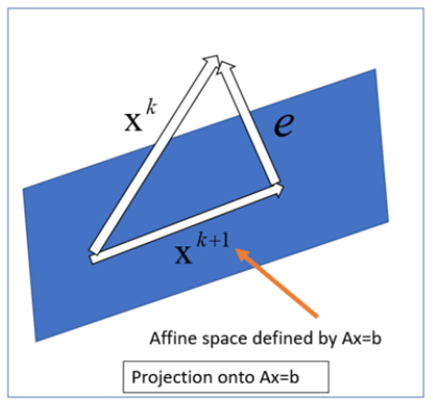

 
$$\begin{array}{l}
{\textrm{From}\;\textrm{the}\;\textrm{above}\;\textrm{diagram}\;\;x}^{k+1} =x^k -e\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\left(1\right)\\
\textrm{Let},x^k =z^k -u^k \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\left(2\right)
\end{array}$$



$$\begin{array}{l}
\textrm{We}\;\textrm{know},Ax^{k+1} =b\\
\textrm{Substituting}\;\textrm{equantion}\;1\;\textrm{we}\;\textrm{get},\\
A\left(x^k -e\right)=b\\
\textrm{On}\;\textrm{expanding}\;\textrm{and}\;\textrm{rearranging}\;\textrm{we}\;\textrm{get},\\
\textrm{Ae}=Ax^k -b\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\left(3\right)\\
\textrm{Now},\textrm{let}\;e=A^T v\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\left(4\right)\\
\textrm{Substituting}\;\textrm{equation}\;4\;\textrm{in}\;3\;\textrm{we}\;\textrm{get},\\
AA^T v=Ax^k -b\\
\textrm{On}\;\textrm{rearranging}\;\textrm{and}\;\textrm{expanding}\;\textrm{we}\;\textrm{get},\\
v=\left(AA^T \right)\left(Ax^k \right)-{\left(AA^T \right)}^{-1} b\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\left(5\right)\\
\textrm{On}\;\textrm{substituting}\;\textrm{equation}\;5\;\textrm{in}\;4\;\textrm{we}\;\textrm{get}\\
e=A^T \left(AA^T \right)\left(Ax^k \right)-A^T {\left(AA^T \right)}^{-1} b\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\left(6\right)\\
\textrm{Substituting}\;\textrm{equations}\;6\;\textrm{and}\;2\;\textrm{in}\;\textrm{equation}\;1\;\textrm{we}\;\textrm{get},\\
x^{k+1} =\left(I-A^T {\left(AA^T \right)}^{-1} A\right)\left(z^k -u^k \right)+A^T {\left(AA^T \right)}^{-1} b
\end{array}$$


Now, we do the z update (using the updated x and the old u)


$$\begin{array}{l}
z^{k+1} =S_{\frac{1}{\rho }} \left(x^{k+1} +u^k \right)\\
\textrm{where}\;\frac{1}{\rho }=\textrm{inverse}\;\textrm{of}\;\textrm{the}\;\textrm{step}\;\textrm{size};\textrm{Both}\;\textrm{step}\;\textrm{size}\;\textrm{and}\;\textrm{penalty}\;\textrm{parameter}\;\textrm{are}\;\textrm{assumed}\;\textrm{to}\;\textrm{be}\;\textrm{the}\;\textrm{same}\;\textrm{to}\;\textrm{get}\\
\textrm{simple}\;\textrm{expression}\;\textrm{with}\;\textrm{only}\;\textrm{one}\;\textrm{hyper}-\textrm{parameter}\ldotp S_{\frac{1}{\rho }} \;\textrm{is}\;\textrm{the}\;\textrm{shrinkage}\;\textrm{parameter}\ldotp \textrm{For}\;\textrm{large}\;\textrm{value}\;\textrm{of}{{\;}^{\prime } \mathit{\mathbf{n}}}^{\prime } ,\;\\
\textrm{relaxation}\;\textrm{and}\;\textrm{shrinkage}\;\textrm{method}\;\textrm{of}\;\textrm{solving}\;\textrm{converges}\;\textrm{faster}\ldotp \textrm{Shrinkage}\;\textrm{will}\;\textrm{come}\;\textrm{only}\;\textrm{if}\;\textrm{L1}\;\textrm{norm}\;\textrm{is}\;\textrm{there}\;\textrm{in}\\
\textrm{the}\;\textrm{formulation}\ldotp \;
\end{array}$$


And now we do the dual update, updating u (updation of multipliers)


$$u^{k+1} =u^k +x^{k+1} -z^{k+1}$$


###  **MATLAB CODE:**

 **Creating the problem and calling the function:**

n = 30;
m = 10;
A = randn(m,n);
 
x = sprandn(n, 1, 0.1*n);
b = A*x;
% rho is the augmented Lagrangian parameter.
% alpha is the over-relaxation parameter (typical 
% values for alpha are between 1.0 and 1.8).
% Here, in the function call statement 
[x] = basis_pursuit(A, b, 1.0, 1.0)

x =          0
         0
         0
         0
         0
   -0.3936
         0
         0
         0
         0


## GROUP TESTING FOR COVID-19 USING COMPRESSED SENSING

### How do we apply the “Gold coin – Compressed Sensing” logic in Group Testing for COVID-19?

In order to quickly test multiple patients for the virus and to the reduce the amount of time that is spent on checking for the virus on many Covid negative patients, group testing was introduced.

 Group testing works like this: First we collect the samples of the group of people who need to be tested, and we divide this sample into two groups of samples, suppose, as given in the below image, we have 8 samples that need to be checked, we divide it into two groups of 4 samples each. The group which yield a positive COVID test result is further analyzed by once again dividing the group and taking the samples of these sub groups. This goes on until we get to the sample that has tested positive.

                         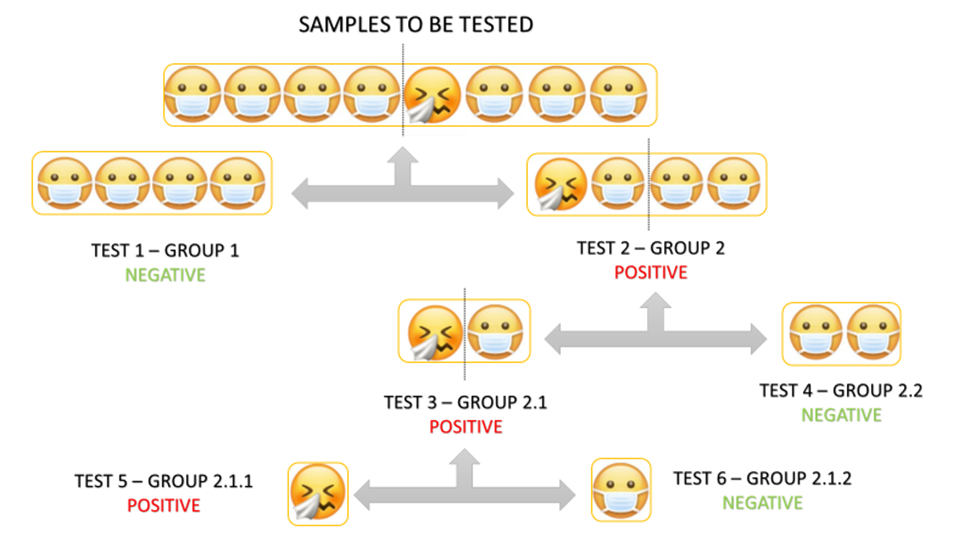

### **Group Testing for Increased Testing Capacity**

 A single negative test  result on a pooled sample indicates all the individuals in that pool are virus free. Pooling samples can be effective with the existing PCR tests. Compressed sending method better that group testing

### **How do we use Compressed Sensing to do this task?**

 Just like how in the first coin problem we discussed above, instead of like the coins numbered from 1 to N, we have samples of people to be tested. Then, we take some m number of tests, and in each test we take some p number of samples. Here, our m vector can have values between 0 to 1, where 0 means that the particular test came out negative and 1 represents the test group that came positive. Then we go follow the same procedures as the coin problems and get the number/index of the sample of a positively tested person. 

**MATLAB CODE:**

A= [1  0  0  1  1 0 1; 0 1 0 1 0 1 1; 0 0 1 0 1 1 1];
% if a person is negative we add one, if the person is positive
% we add 0
% so the b vector value for a group with all negatively tested people
% would be 7 (expected measurement) -7(observed/calculatedd measurement) =0 
% suppose a person in a group has tested positive then 7-6=0
b=[0;1;1];
%so 0 means the group came out to be negative and 1 means the group came
%out to be positive
cvx_begin quiet
variable x(7)
minimize( norm(x,1))
subject to
        A*x==b;
cvx_end
disp("solution vector is")

solution vector is


x

x =    -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.0000
    0.0000


disp("The person who has tested positive is person number ")

The person who has tested positive is person number 


myMax = max(x);
find(x==myMax)

ans = 6

## **ERROR CORRECTION CODES (COVID-19)**

 ECC (Error Correction Codes) is very prevalent in today’s world. It is used for limiting the different errors in the data that occur over some disturbed communication channel. This limiting can be done in many different ways.

 Here our main objective is to design pooled testing using 'error correction coding’ combined with compressed sensing to prove that pooled testing is not less reliable that testing individual separately.  With only group testing/compressed sensing you can only reduce the required number of tests. 

The main aim of error correcting pooled testing is to increase the reliability of the PCR tests and not to reduce the required number of tests as in group testing/compressed sensing.We will now do the mathematical formulation for performing the test through error correction codes.

### **Formulation**

So now we consider ‘n’ samples of ‘n’ people. With these ‘n’ samples, we shall perform ‘m’ PCR tests to determine the amount/quantity of the COVID-19 viruses in these given samples. 

From each of these ‘m’ conducted tests, we will make a pooled sample by mixing the samples of different individuals. 

Then we take a matrix   $P\;\epsilon \;{\left\lbrace 0,1\right\rbrace }^{\textrm{mxn}}$   (sparse binary matrix) which will tell us the participation of the ‘n’ samples in ‘m’ tests. This means that the sample of the j-th person will participate in the i-th test if $P_{\textrm{ij}} =1$else it wont i.e, $\left(P_{\textrm{ij}} =0\right)$.

So hence the number of 1's in i-th column of P is the number of tests that the sample of the i-th person will participate in.

Next we have $W\;\epsilon \;{\left\lbrack 0,1\right\rbrack }^{\textrm{mxn}\;}$which is our weight matrix where we will be modeling the allocation of the person’s sample. The weight can be any value from 0 to 1.

Now we have set up our measurement matrix $A$ such that:


$$A=P*W$$


The given ‘m’ samples will go through ‘m’ PCR tests to get the estimate the amount of DNA present in it. Due to a lot of noises and errors caused by various factors such as dilutions, sample contamination and mistakes during the testing, the final measurements from the real time PCR tests is given as :


$$y=f\left(\textrm{Ax}\right)+v+e$$


where ‘v’ and ‘e’ are the noise from the observations and the gross error respectively.

What we need to find is x (sample measurements) for n people and m tests measurements.

### **Expanded Bipartite Graphs**

An expanded graph is a graph that is highly sparse and has strong connectivity properties and bipartite means that the vertices of that graph can be divided into two separate disjoint and independent sets also making sure that every edge connects to vertices from both the sets only.

These graphs are very commonly used for error correcting codes.

 So based on this graph, we design our matrix P. 

Also, the low commonness among the population lets us assume that x is also sparse or almost sparse. It is also assumed that the gross error ‘v’ is sparse because things like dilution and contamination happens very rarely.

Now considering all the above assumptions we can formulate it as a constrained optimization problem as follows: 


$$\begin{array}{l}
\textrm{minimize}\;{\left\|z\right\|}_1 +\lambda {\left\|y-\textrm{Az}-u\right\|}_1 \\
\;\;\;\;\;\;\;\;\;\;\;\textrm{subject}\;\textrm{to}\;{\left\|u\right\|}_2 \le \epsilon \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;z\ge 0
\end{array}$$


where  $\left|\right|z\left|{\left|\right.}_1 \right.$ is the sum of the absolute values in z. Here z is used as an estimate for x, u as an estimate for v and  $y-\textrm{Az}-u\;$as an estimate for e.

We are using l1 norm optimization as it gives good performance without much of computation complexity.

Once we get the estimation for x, if  $z_j \ge \tau$ where $\tau \;$ is some given threshold value ,then we can say that the j-th person is infected with the virus and tested **positive**, else we declare it as **negative**.

## **Signal Reconstruction/Restoration Using Compressed Sensing**

The Nyquist-Shannon sampling theorem states that to restore a signal exactly and uniquely, you need to have sampled with at least twice its frequency. Of course, this theorem is still valid; if you skip one byte in a signal or image of white noise, you can’t restore the original. But most interesting signals and images are not white noise. When represented in terms of appropriate basis functions, such as trig functions or wavelets, many signals have relatively few non-zero coefficients. In compressed (or compressive) sensing terminology, they are sparse.

When you say that it is a sparse matrix or an array, it means that most of the elements in the matrix or array are zero.

Considering a raw image/signal in terms of a vector $f$ with many components. We can assume that $f$can be represented as a linear combination of certain basis functions :

                                                                
$$f=\psi c$$


where $\psi$ is the discrete cosine transform and most of the coefficients $c$ are effectively zero, so that $c$ is sparse.

The sampling of signal involves another linear operator :

                                                                    
$$b=\phi f$$


where $b$ is a few samples from $f$ and $\phi$ is a subset of the rows of the identity operator.

Now to reconstruct our signal, we must try to recover the coefficients by solving:

                                                
$$\textrm{Ax}=b\;\;\textrm{where}\;A=\phi \psi$$


Once we have the coefficients we can recover the signal by solving/computing:

                                                    
$$f\approx \psi x$$


** Discrete Cosine Transform:**

The DCT is a technique allowing the conversion of a signal into elementary frequency components. More in particular, in the DCT the input signal is represented as a linear combination of weighted basis functions that are related to its frequency components.

In general, the DCT does not directly reduce the number of bits required to represent the block. For instance, for an 8 × 8 block of 8-bit pixels, the DCT produces an 8 × 8 of 11-bit coefficients due to the range of coefficient values. However, considering that the DCT concentrate, the low-frequency coefficients, and remaining other coefficients are mainly zero, the compression can be achieved by transmitting the near-zero coefficients and by quantizing and coding the remaining coefficients.

m = 500; %no of random samples taken into consideration
n = 5000; %dimension of vector f
% raw signal regarded as a vector f with 5000 components.
t = linspace(0, 1/8, n);
% we sample this tone for 1/8 of a second 
f = sin(1394*pi*t) + sin(3266*pi*t);
% selecting 10% samples of n = m no of samples
%sorting not necessary but used for convenience in plotting
b = sort(randsample(n,m));
figure
plot(t,f) %plotting the signal
ylim([-2 2])
xlim([0 0.030])
title('Original Signal')
xlabel('time')
ylabel('signal')
figure
t2 = t(b);
f2 = f(b);
plot(t2,f2) %plotting the random samples
ylim([-2 2])
xlim([0 0.030])
title('Random samples signal from original signal')
xlabel('time')
ylabel('sample signal')
A = idct(eye(n));
% A = phi * psi where phi = subset of our identity operator 
% and psi is direct cosine transform
% A performs both a sampling and a transformation 
% from spectral to temporal domains.
A = A(b,:);
% A  is made up of rows sampled from the domain transform matrix psi. 
% The psi matrix is the idct acting upon the columns of I. 
% The matrix product psi*x is the equivalent to doing idct(x).
cvx_begin 
variable vx(n)
minimize(norm(vx,1));
subject to
A*vx == f2';
cvx_end

 
Calling SDPT3 4.0: 10000 variables, 500 equality constraints
------------------------------------------------------------

 num. of constraints = 500
 dim. of socp   var  = 10000,   num. of socp blk  = 5000
 number of nearly dependent constraints = 21
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.6e-01|7.0e+01|7.6e+05| 1.056772e+04  0.000000e+00| 0:0:02| chol  2  2 
 1|1.000|0.900|9.8e-09|7.0e+00|1.1e+05| 1.378179e+04  4.634382e+02| 0:0:04| chol  1  1 
 2|1.000|0.905|1.8e-08|6.8e-01|1.8e+04| 1.070465e+04  2.397083e+02| 0:0:07| chol  1  

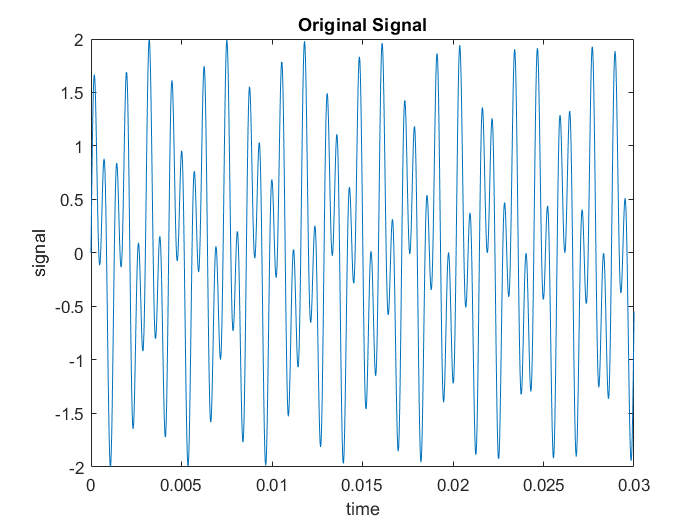

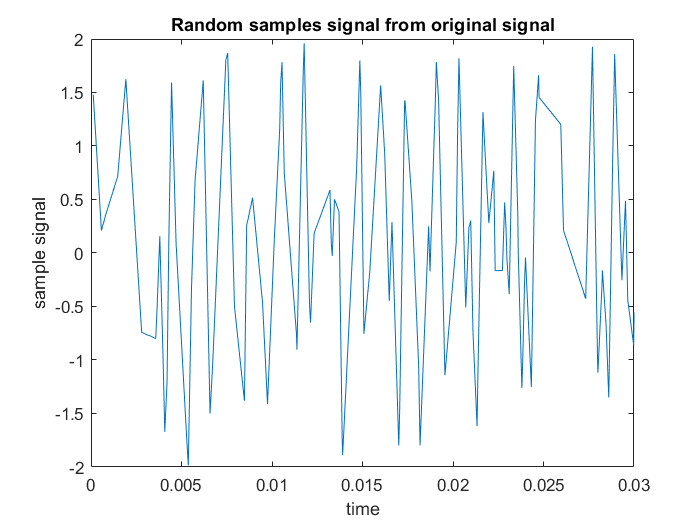

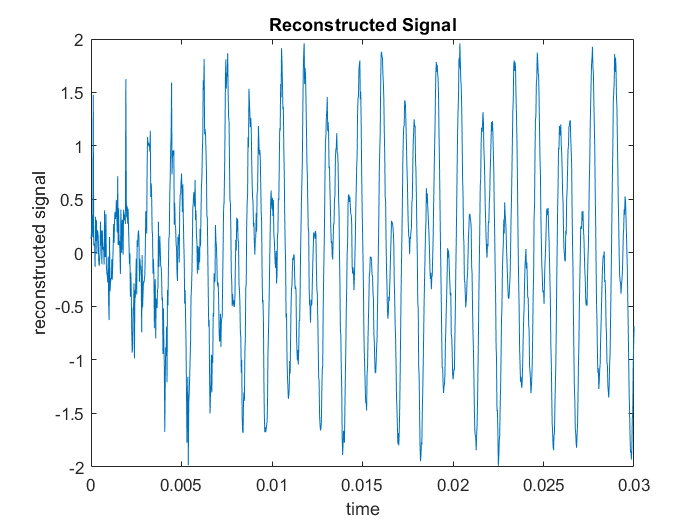

x = squeeze(vx);
rsignal = idct(x);
figure
plot(t,rsignal) %plotting the signal
ylim([-2 2])
xlim([0 0.030])
title('Reconstructed Signal')
xlabel('time')
ylabel('reconstructed signal')
%the quality of the reconstruction degrades noticeably at and around t=0. 
% This is probably due to our sample interval violating the periodic boundary 
% condition requirements of the cosine transform.
sound(f)
pause(2.5)

sound(x)

**Reconstruction of an Image (a 2D Signal)**

What we had done previously was for a one-dimensional signal, whereas here we shall do the image reconstruction for an image.

Here we have used SciPy’s *idct* and *dct* functions to act on the columns of the matrix.

Also one major difference here in the 2D case is the generation of the A matrix.

Creating the A matrix for 2D image data takes a little more ingenuity than it did in the 1D case. In the derivation that follows, we’ll use the Kronecker product ⊗ and the fact that the 2D discrete cosine transform is separable to produce our operator A .

The Kronecker product ⊗ is nothing but the operation on two matrices of arbitrary size resulting in a block matrix.

**Python Code**

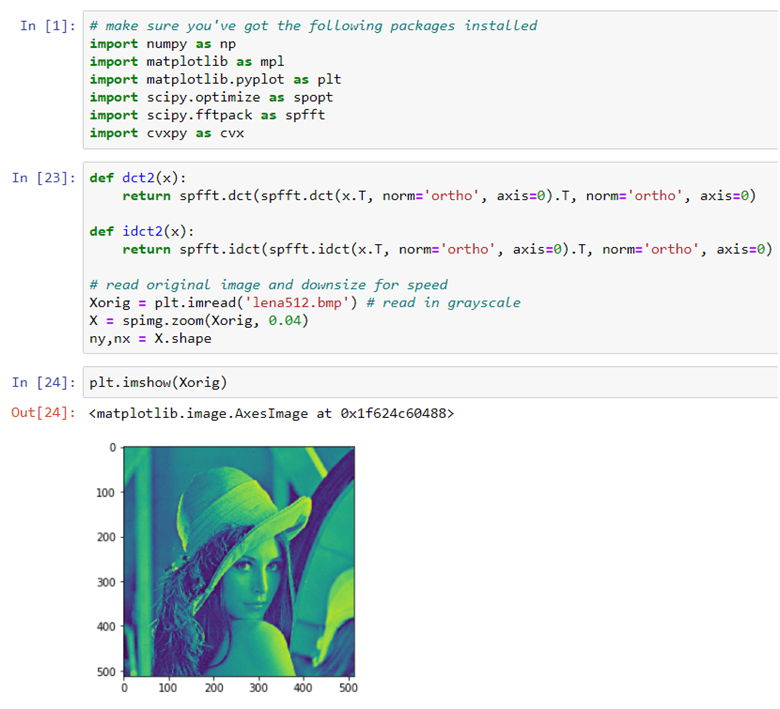

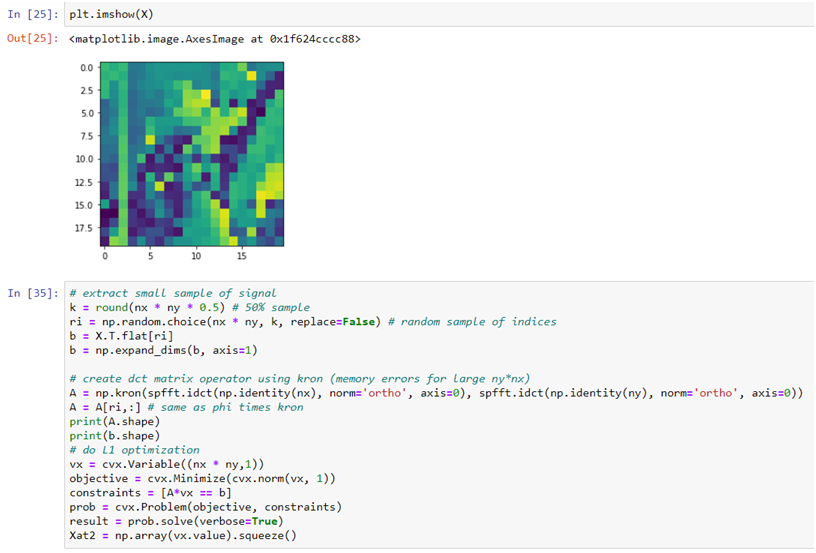

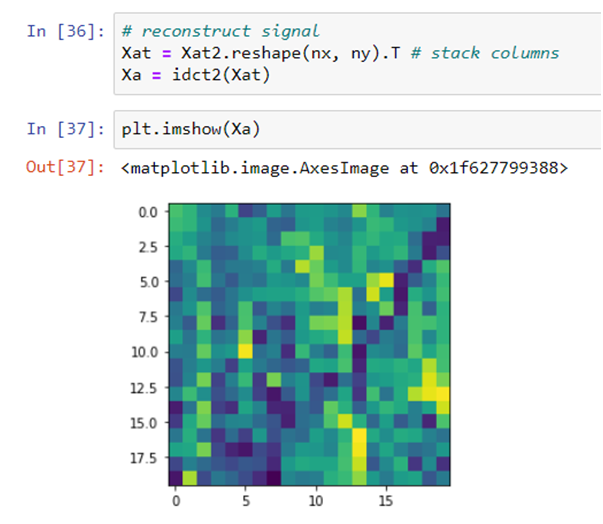

## TOTAL VARIATION MINIMIZATION USING ADMM (SIGNAL DENOISING)

Total Variation Minimization is used in real life applications like signal denoising. Unlike our conventional Low Pass filters, the Total Variation Minimization Denoising is defined in terms of the optimization problem. Total variation is also used in applications like compressed sensing, deconvolution, interpolation etc apart from being used for denoising purposes. 


$$\begin{array}{l}
\textrm{minimize}\;\frac{1}{2}{\left\|x-b\right\|}_2^2 +\lambda \sum_{i=1}^{n-1} \left|x_{i+1} -x_i \right|,x\in R^n \\
\Rightarrow \textrm{minimize}\;\frac{1}{2}{\left\|x-b\right\|}_2^2 +\lambda {\left\|z\right\|}_1 \\
\textrm{subject}\;\textrm{to}\;z=\textrm{Dx}
\end{array}$$


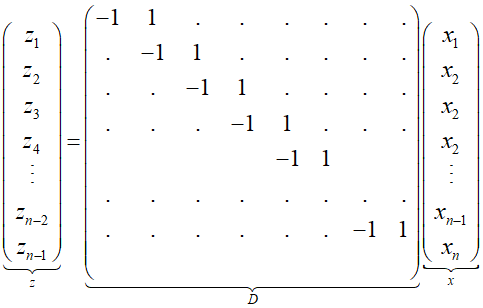


$$\begin{array}{l}
\textrm{Augmented}\;\textrm{Lagrangian}\;\textrm{is}\;\\
L\left(x,z,y\right)=\frac{1}{2}{\left\|x-b\right\|}_2^2 +\lambda {\left\|z\right\|}_1 +y^T \left(\textrm{Dx}-z\right)+\frac{\rho }{2}{\left\|\textrm{Dx}-z\right\|}_2^2 \\
\textrm{The}\;\textrm{ADMM}\;\textrm{updates}\;\textrm{are}\\
x^{k+1} ={\left(I+\rho D^T D\right)}^{-1} \left(b+\rho D^T \left(z^k -\frac{y^k }{\rho }\right)\right)\\
z^{k+1} =S_{\frac{\lambda }{\rho }} \left(Dx^{k+1} +\frac{y^k }{\rho }\right)\\
y^{k+1} =y^k +\left(Dx^{k+1} -z^k \right)\\
\textrm{On}\;\textrm{letting}\;\frac{y^k }{\rho }=u^k \\
x^{k+1} ={\left(I+\rho D^T D\right)}^{-1} \left(b+\rho D^T \left(z^k -u^k \right)\right)\\
z^{k+1} =S_{\frac{\lambda }{\rho }} \left(Dx^{k+1} +u^k \right)\\
u^{k+1} =u^k +\left(Dx^{k+1} -z^k \right)
\end{array}$$


% Total variation denoising with random data

n = 2;

x0 = ones(n,1);
for j = 1:3
    idx = randsample(n,1);
    k = randsample(1:10,1);
    x0(ceil(idx/2):idx) = k*x0(ceil(idx/2):idx);
end
b = x0 + randn(n,1); % random noisy signal

lambda = 5; %regularization parameter - controls degree of smoothing of the signal

x = total_variation(b, lambda, 1.0,1.0)            

x =   196.0260
    1.8707


Using the similar procedure in majorization - minimization method (which is similar to ADMM; it is a powerful iterative algorithm for optimization problems),

we are going to denoise a randomly generated signal. 

The x-update of TVD (Total variation denoising) is given to us as 


$$\begin{array}{l}
x_{k+1} =y-D^T {\left(\frac{1}{\lambda }\textrm{diag}\left(\left|Dx_k \right|\right)+DD^T \right)}^{-1} \textrm{Dy}\\
\textrm{where}\;y\;\textrm{is}\;\textrm{the}\;\textrm{noisy}\;\textrm{signal},x\;\textrm{is}\;\textrm{the}\;\textrm{denoised}\;\textrm{signal}\;\textrm{we}\;\textrm{have}\;\textrm{to}\;\textrm{get},\lambda \;\textrm{is}\;\textrm{the}\;\textrm{regularization}\;\textrm{parameter}\;\textrm{for}\;\textrm{the}\;\textrm{smoothness}\\
DD^T \;\;\textrm{is}\;a\;\textrm{tridiagonal}\;\;\textrm{sparse}\;\textrm{matrix}\\
\textrm{The}\;\textrm{first}\;\textrm{order}\;\textrm{difference}\;\textrm{of}\;\textrm{an}\;N-\textrm{point}\;\textrm{signal}\;x\;\textrm{is}\;\textrm{given}\;\textrm{by}\;\textrm{Dx}
\end{array}$$
 

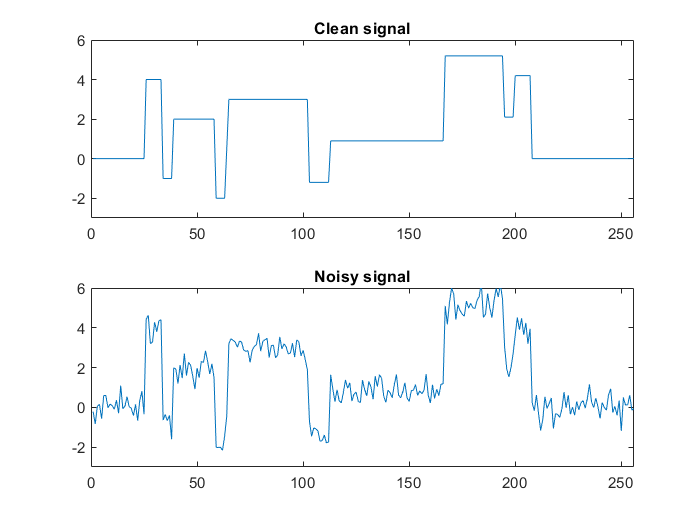

% Create data

s = load('blocks.txt');         % blocks signal
y = load('blocks_noisy.txt');   % noisy blocks signal

N = 256;                        % N : signal length
sigma = 0.5;                    % sigma : standard deviation of noise

figure(1)
clf
subplot(2,1,1)
plot(s)
ax = [0 N -3 6];
axis(ax)
title('Clean signal')

subplot(2,1,2)
plot(y)
axis(ax)
title('Noisy signal')

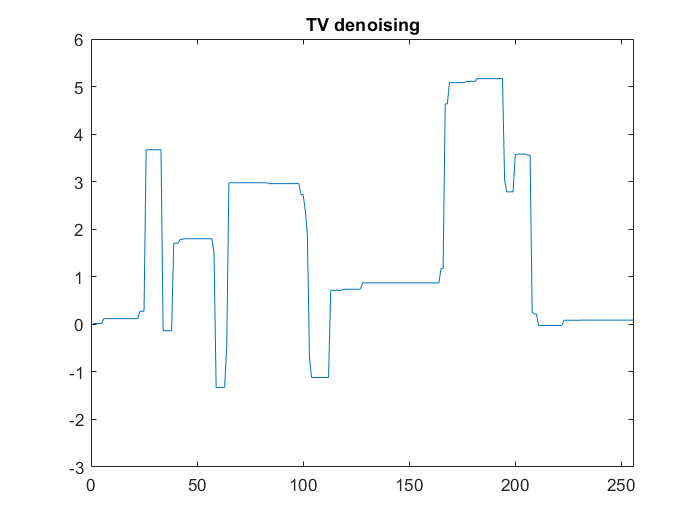


% TV Denoising
% Run TV denoising algorithm (MM algorithm)

lam = 1.5;                        
% lam: regularization parameter
% λ > 0 controls the degree of smoothing.
Nit = 50;                          % Nit: number of iterations
x = tvd_mm(y, lam, Nit);   % Run MM TV denoising algorithm

figure(2)
clf

plot(x)
axis(ax)
title('TV denoising')

## OTHER APPLICATIONS

-  Single Pixel Camera

-  Data Compression

-  Pattern Recognition

-  Speech and Language Processing 

-  Facial recognition

-  Image and signal restoration and recovery

-  Image reconstruction in holography

-  Magnetic resonance imaging

#### **Function Definitions:**

function x = total_variation(b, lambda, rho,alpha)
MAX_ITER = 1000;
n = length(b);
e = ones(n,1);
D = spdiags([e -e], 0:1, n,n);  %Sparse matrix formed from diagonals

x = zeros(n,1);
z = zeros(n,1);
u = zeros(n,1);

I = speye(n);
DtD = D'*D;

for k = 1:MAX_ITER

    % x-update
    x = (I + rho*DtD) \ (b + rho*D'*(z-u));

    % z-update with relaxation
    zold = z;
    Ax_hat = alpha*D*x +(1-alpha)*zold;
    a = Ax_hat + u;
    kappa = lambda/rho;
    z =  max(0, a-kappa) - max(0, -a-kappa);
   
    % u-update
    u = u + Ax_hat - z;
end
end

function [x] = tvd_mm(y, lam, Nit)
% INPUT
%   y - noisy signal
%   lam - regularization parameter
%   Nit - number of iterations
%
% OUTPUT
%   x - denoised signal

y = y(:);                                              % Make column vector
N = length(y);

I = speye(N);
D = I(2:N, :) - I(1:N-1, :);
DDT = D * D';

x = y;                                                 % Initialization
Dx = D*x;
Dy = D*y;

for k = 1:Nit
    F = sparse(1:N-1, 1:N-1, abs(Dx)/lam) + DDT;       % F : Sparse banded matrix
    x = y - D'*(F\Dy);                                 % Solve banded linear system
    Dx = D*x;
end
end

function [z] = basis_pursuit(A, b, rho, alpha)
% Global constants and defaults
MAX_ITER = 1000;
% Data preprocessing
[m n] = size(A);
% ADMM solver
x = zeros(n,1);
z = zeros(n,1);
u = zeros(n,1);
% precompute static variables for x-update (projection on to Ax=b)
AAt = A*A';
P = eye(n) - A' * (AAt \ A);
q = A' * (AAt \ b);
for k = 1:MAX_ITER
% x-update
    x = P*(z - u) + q;
% z-update with relaxation
    zold = z;
    x_hat = alpha*x + (1 - alpha)*zold;
%z = shrinkage(x_hat + u, 1/rho);
    a = x_hat+u;
    kappa = 1/rho;
    z = max(0, a-kappa) - max(0, -a-kappa); %shrinkage
    u = u + (x_hat - z);
end
end